# This Live script is for testing the kinematicTree class code

Set up some geometric properties:

L = 1.1; % link length

% offset homogeneous matrix transforms
gT(:,:,1) = TrotY(pi/2);
gT(:,:,2) = TrotY(-pi/2)*Ttz(L);
gT(:,:,3) = Ttz(L)*TrotX(-pi/2);
gT(:,:,4) = Tty(-L)*Ttx(L);
gT(:,:,5) = TrotX(pi/2)*Ttz(L);
gT(:,:,6) = Ttz(L)*TrotY(pi/2);
gT(:,:,7) = Ttx(-L)*Tty(-L);
gT(:,:,8) = gT(:,:,5);
gT(:,:,9) = gT(:,:,6);

% we used here some ScrewCalculus package functions
% i.e.
homogRotation = TrotY(pi/2)

homogRotation =     0.0000         0    1.0000         0
         0    1.0000         0         0
   -1.0000         0    0.0000         0
         0         0         0    1.0000


Define now the joints type of the kinematic tree with the helix lead convention: h = 0 -> revolute; h=Inf -> prismatic; h=finiteValue \= 0 -> helical

h(1:9) = 0; % initialize all as revolute
% turn to prismatic / helical the required ones
h(2) = 0; 
h(5) = Inf;
h(8) = Inf;

Define now the arcs' predecessors and successors array and plot the graph

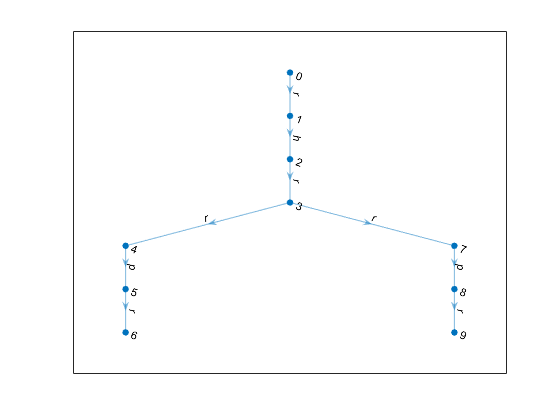

p = [0,1,2,3,4,5,3,7,8]; % predecessor array
s = 1:9;                 % successor array

% create the graph (Remember matlab indexing origin starts from 1)
G = digraph(p+1, s+1);

jointLabels = {'r','r','r','r','r','r','r','r','r'};
jointLabels{2} = 'h';
jointLabels{6} = 'p';
jointLabels{8} = 'p';

kinematicTreeGraph = plot(G, 'NodeLabel',{'0','1','2','3','4','5','6','7','8','9'}, 'EdgeLabel', jointLabels);

Create the kinematicTree:

tree = kinematicTree(p, s, gT, h); % p and s define the graph, gT defines the initial offset between joints and h defines the joint types

Test some functionalities, like the autoamically computed lambda, mu, k and ni arrays:

lambda = tree.lambda  % array of parent nodes

lambda =      0     1     2     3     4     5     3     7     8


mu = tree.mu          % cell array of direct children nodes (each cell element contains an array of childrens)

mu = 1×10 cell array
    {[1]}    {[2]}    {[3]}    {[4 7]}    {[5]}    {[6]}    {1×0 double}    {[8]}    {[9]}    {1×0 double}


k = tree.k            % cell array of all the parents of each node

k = 1×9 cell array
    {[1]}    {[1 2]}    {[1 2 3]}    {[1 2 3 4]}    {[1 2 3 4 5]}    {[1 2 3 4 5 6]}    {[1 2 3 7]}    {[1 2 3 7 8]}    {[1 2 3 7 8 9]}


ni = tree.ni          % cell array of all the childrens (direct and subsequent) of each node

ni = 1×10 cell array
    {[0 1 2 3 4 7 5 8 6 9]}    {[1 2 3 4 7 5 8 6 9]}    {[2 3 4 7 5 8 6 9]}    {[3 4 7 5 8 6 9]}    {[4 5 6]}    {[5 6]}    {[6]}    {[7 8 9]}    {[8 9]}    {[9]}


! Warning ! Due to matlab's index origin the tree properties mu and ni have mismathced indexes: i.e. mu{i} and ni{i} are associated to the (i-1)-th node, while lambda(i), k{i}, p(i) and s(i) are associated to the i-th node.

Now define a joint array and build the kinematic manipulator:

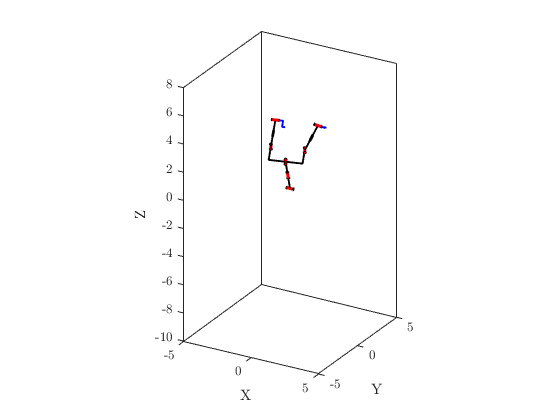

q = (1:9).*0;
q(1) = 15*pi/180;
q(2) = 0.5;
q(3) = q(1);
q(6) = 1;
q(4) = q(1);

% compute the forward kinematics
tree.FWKin(q);

% plot the manipulator
tree.plotInit;
view(gca, 30, 25);
xlabel(gca, 'X');
ylabel(gca, 'Y');
zlabel(gca, 'Z');
set(gca, 'box', 'on')
xlim([-5 5])
ylim([-5 5])
zlim([-10 8])

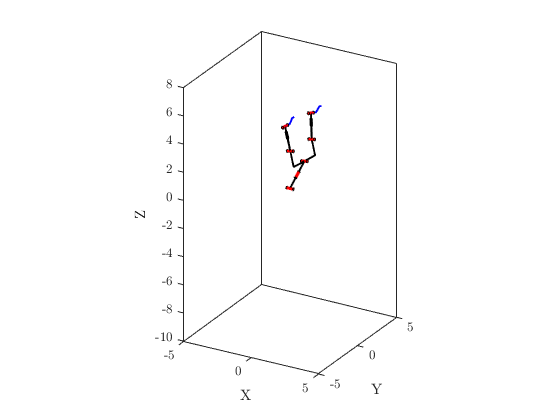

% change joins value and update on the fly
values = linspace(-0.5,0.5,100);
values = [values,fliplr(values)];
for i = 1:200 % loop an animation
    q([2,5,8]) = values(i);  % move the prismatic joints
    q([6,9]) = 5.*values(i); % rotate some revolute joints
    q([1,3]) = 2.*values(i);
    q(2) = 10.*values(i);    % rotate the helical joint
    tree.FWKin(q);           % update the kinematics
    tree.updatePlot();       % update plot
    pause(0.001);
end

To plot each joint correctly the tree Object stores each matrix transform  (both local transform and the global chain):

Glocal         = tree.G_local;   % local matrix transofrm with POE formulation ( = g_i-1,i(0)*expTwist(twist_i*q_i))
GlocalJ        = tree.G_localJ;  % local matrix transofrm of joint ( = expTwist(twist_i*q_i))
Gglobal        = tree.G_global;  % global matrix transform of i-th body
GglobalToJoint = tree.G_globalJ; % global matrix transform up to the i-th joint fixed to the lambda(i)-th body

% i.e 4-th body
Glocal{4}

ans =     0.9659   -0.2588         0    1.1000
    0.2588    0.9659         0   -1.1000
         0         0    1.0000         0
         0         0         0    1.0000


GlocalJ{4}

ans =     0.9659   -0.2588         0         0
    0.2588    0.9659         0         0
         0         0    1.0000         0
         0         0         0    1.0000


Gglobal{4}

ans =     0.2098    0.1909   -0.9589   -0.0940
    0.9495   -0.2738    0.1533    2.9586
   -0.2333   -0.9427   -0.2387    2.2772
         0         0         0    1.0000


GglobalToJoint{4}

ans =     0.1533    0.2387   -0.9589   -0.0940
    0.9880   -0.0187    0.1533    2.9586
    0.0187   -0.9709   -0.2387    2.2772
         0         0         0    1.0000


Compute the body jacobian with the local POE formulation of a node (e.g. from root to 8-th node). The joint values are the same used for the FWKin call (intermediate matrices are stored in memory and not computed)

% jacobians
bodyJac_0to8 = tree.bodyJacobian(8)

bodyJac_0to8 =    -2.7700    0.0000    1.7000    0.6000         0
   -0.6220   -2.0248   -0.0000         0         0
    0.7204   -0.0000    1.1000         0    1.0000
    0.1533    0.8415         0         0         0
   -0.9589    0.0000    1.0000    1.0000         0
   -0.2387    0.5403    0.0000    0.0000         0


bodyJac_0to9 = tree.bodyJacobian(9)

bodyJac_0to9 =     1.0503    1.7658    0.8813   -0.0000    0.8011         0
    0.2023    2.3637   -0.6583    0.0000   -0.5985         0
   -3.8248   -0.0000    2.8000    1.7000    0.0000         0
    0.3827    0.4329   -0.5985   -0.5985         0         0
    0.9111   -0.3234   -0.8011   -0.8011         0         0
    0.1533    0.8415    0.0000    0.0000         0    1.0000


% 
qdot = ones(1,9).';
% twists
bodyTwist_0to8 = bodyJac_0to8*qdot(tree.k{8})

bodyTwist_0to8 =    -0.4700
   -2.6469
    2.8204
    0.9947
    1.0411
    0.3016


bodyTwist_0to9 = bodyJac_0to9*qdot(tree.k{9})

bodyTwist_0to9 =     4.4985
    1.3092
    0.6752
   -0.3814
   -1.0146
    1.9947


Inverse dynamics computation

Fext = zeros(6,tree.Nb); % external forces on each node
% Fext(3,tree.Nb-1) = 10000; 
for i = 1:tree.Nb
    tree.I{i} = eye(6); % inertia matrices
    tree.I{i}(4:6,4:6) = tree.I{i}(4:6,4:6).*10;
end

Vroot = [0;0;0;0;0;0]; % twist at root node
Vrootdot = Vroot;      % twist derivative at root node

qd = zeros(1000,tree.Nb);        % joint velocities
qdd = ones(1000,tree.Nb);        % joint accelerations

% inverse dynamics
tau = nan(1000, tree.Nb);
tic
for i = 1:1000
    [tau(i,:), F] = tree.RNEAdyn(q,qd(i,:),qdd(i,:),Vroot,Vrootdot,Fext);
end
time = toc;
disp("1000 iterations of RNEA computed in: " + time + " seconds")

1000 iterations of RNEA computed in: 0.84664 seconds


disp("average of " + time + " ms per iteration")

average of 0.84664 ms per iteration


Direct dynamics computation using pevious inverse dynamic results

qddNew = nan(1000,tree.Nb);
tic
for i = 1:1000
    qddNew(i,:) = tree.ABAdyn(q,qd(i,:),tau(i,:),Vroot,Vrootdot,Fext);
end
time = toc;
disp("1000 iterations of ABA computed in: " + time + " seconds")

1000 iterations of ABA computed in: 1.0588 seconds


disp("average of " + time + " ms per iteration")

average of 1.0588 ms per iteration



% perform validation 
isequal(chop(qdd-qddNew, 1e-6), zeros(1000,9))

ans = logical
   1


Integrate the dynamics with a given input torques (forward Euler integration)

deltaT = 0.005;      
Vrootdot = [0;0;9.81;0;0;0];             % simulate gravity by accelerating the base
tau = zeros(10000,tree.Nb);              % unactuate all joints
tau(:,1) = 0.*ones(1,10000);             % actuate just the first revolute joint
qd = zeros(1,tree.Nb);
ub = 0.5;                                % upper bound for prismatic joints
lb = -0.5;                               % lower bound for prismatic joints
Fext = zeros(6,tree.Nb);
xdot = @(x, u) [x(tree.Nb+1:end), tree.ABAdyn(x(1:tree.Nb),x(tree.Nb+1:end),u,Vroot, Vrootdot, Fext)];
x0 = [q, qd];
for i = 1:10000
    tree.FWKin(q);
    tree.updatePlot();
    pause(0.01)
    x0 = RK4_integrator(x0, tau(1,:), xdot, deltaT, 1);
    q = x0(1:tree.Nb);
    
    % check for bounds
    if q(5) < lb
        q(5) = lb;
        qd(5) = 0; % reset joint velocity when bound is hit
    end
    if q(5) > ub
        q(5) = ub;
        qd(5) = 0;
    end
    if q(8) < lb
        q(8) = lb;
        qd(8) = 0;
    end
    if q(8) > ub
        q(8) = ub;
        qd(8) = 0;
    end
    
    if qd(1) > 10
        qd(1) = 10;
    end
    x0(1:tree.Nb) = q;

end

Control law is required to obtain a more "regular" motion

q = rand(9,1);
qd = rand(9,1);
tau = rand(9,1);
tic;
for i = 1:1000
   compiledABA(q, qd, tau);
end
time = toc;
disp("1000 iterations of compiled ABA computed in: " + time + " seconds")
disp("average of " + time + " ms per iteration")